# Symbolic variables definitions

clear;   close all ;
ref = CoolPropPyWrapper('HEOS::R134a');

CoolProp version: 6.4.1


load ("HiFi_model_data.mat")
delta_X = 0.00001;   

% general interface variables
syms h [1 7]
syms p [1 5]
syms T [1 7]
syms m_dot_1 m_dot_2 m_dot_3 m_dot_4 m_dot_5  


% variables in f
syms M_PJJ M_Con T_m Q_rm Q_ma M_m Cp_m m_dot_air m_dot_bar_air T_mlv Q_amlv Q_mlv Q_mvmlv sigma T_mv Q_amv Q_mv M_lv M_v  m_dot_bub 

syms T_mlv_dot T_mv_dot M_lv_dot M_v_dot T_air_dot T_box_dot T_cargo_dot



% pipe joining junction
syms m_dot_2_PJJ

% compressor 2
syms V_1_COM2 V_C_COM2 v_1_COM2 v_2_COM2 omega p_i1_COM2 p_i2_COM2 gamma kl_1 kl_2 C_cp C_cvhtp syms m_dot_2_COM2

% compressor 1
syms V_1_COM1 V_C_COM1 v_1_COM1 v_2_COM1 omega p_i1_COM1 p_i2_COM1 gamma kl_1 kl_2 C_cp C_cv

% condenser
syms Q_rm lambda M_Con V_i_Con v_Con UA_rm T_r T_m UA_ma T_ambi U_fan_1 m_dot_3_Con	

% valve
syms Theta_1 Theta_2 K v_CTV_in v_EV_in fp

% flash tank
syms N M

% evaporator 
syms sigma v_Eva V_i_Eva T_retfan T_ret Q_fan_2 m_dot_air Cp_air T_retsh U_fan_2 U_star_P U_star_m_dot 
syms V_dot_bar_air rho_air UA_1 UA_2 UA_3 T_lv Pi h_v V_lv h_lv h_bub m_dot_bub T_sup

% box
syms T_air Q_ca Q_ba Q_cool M_air 
syms T_box Q_amb M_box Cp_box
syms T_cargo M_cargo Cp_cargo
syms T_ambi UA_amb UA_ba UA_cargo T_v





%T1        = 33.6;
% T1        = out.logsout{27}.Values.Data(end,3);
T2        = 22.2 + 273.15;
% T2        = out.logsout{28}.Values.Data(end,3);
%T3        = 48.3;    % found from Kresten Sim
% T3        = out.logsout{25}.Values.Data(end,3);
T7        = -5 + 273.15;
% T7        = out.logsout{26}.Values.Data(end,3);

p1        = 4.5 * 100000;
% p1        = out.logsout{28}.Values.Data(end,1);
p2        = 7.8 * 100000;
% p2        = out.logsout{25}.Values.Data(end,1);
p3        = 7.8 * 100000;
% p3        = out.logsout{3}.Values.Data(end,1);
p5        = 1.9 * 100000;
% p5        = out.logsout{26}.Values.Data(end,1);



h5         = 4.057e5;
% h5        = out.logsout{21}.Values.Data(end,2);
% h6         = 1.8527e5;
h6         = 2.253e5;
% h6        = ref.HTP(-11.081067,1.9236912);
h_bub      = 3.9203e5;    %ref.HDewP(1.923)

h7 = ref.HTP(-5.54516,1.9037555); 


V_1_COM1   = 50e-6;
V_1_COM2   = V_1_COM1/2;
V_C_COM1   = V_1_COM1*0.05;
V_C_COM2   = V_1_COM2*0.05;

gammaT1 = (out.logsout{28}.Values.Data(end,3) + out.logsout{26}.Values.Data(end,3)) /2;
gammaP1 = (out.logsout{28}.Values.Data(end,1) + out.logsout{26}.Values.Data(end,1)) /2;
gammaT2 = (out.logsout{28}.Values.Data(end,3) + out.logsout{25}.Values.Data(end,3)) /2;
gammaP2 = (out.logsout{28}.Values.Data(end,1) + out.logsout{25}.Values.Data(end,1)) /2;



gamma1     = ref.CpRatioTP(gammaT1, gammaP1); %T=(22-5)/2 degC    p=(1.9+4.5)/2 bar,   see also freom r134a side 25
gamma2     = ref.CpRatioTP(gammaT2, gammaP2); %T=(48+22)/2 degC    p=(4.5+7.7)/2 bar,   see also freom r134a side 34



UA_ma     = 650;
UA_rm     = 1500;

Cp_air    = 1005;


Vi_eva    = 10e-3;

UA_1      = 3510;
UA_2      = 1930;
UA_3      = 50;

T_lv      = -11.3674 + 273.15;    %ref.TBubP(1.9)

T_ret     = 268.9;    


M_air     = (13.4*2.35*2.46)*1.225;      %H*L*B*density


M_cargo   = 1000;
Cp_cargo  = 447;
UA_cargo  = 20;

% Operating points
% ----------------------------------
omega_op   = 28;
Theta_1_op = 0.01 * 19.5;
Theta_2_op = 0.01 * 12.2;
U_fan_1_op = 0.01 * 63.8;
U_fan_2_op = 0.01 * 62.8;
T_ambi_OP  = 273.15 + 20; %from eTRu_prototype_2_start_sim :)

C          = 0.64;
A          = ((20/2)^2)*pi*10^-6;
K          = C*A;

lambda     = 0.1;

Cp_m       = 900;
M_m        = 30;
V_i_Eva    = 14*1.8*6*(0.005^2)*pi; %nr_pipes*length*area

UA_ba      = 25;    
UA_amb     = 25;
Cp_box     = 447;
M_box      = 1000;
kl_1       = 1/2200;
kl_2       = 1/2200; 
rho_air    = 1.225;

% Unknown as of 08/04
% -----------------------------------



T_r             = 30 + 273.15;
p4              = p5;


v_CTV_in        = 0.0008;          %Lookuptable defined below
v_EV_in         = 0.01;            %Lookuptable defined below
v_Eva           = ref.VPX(p5*1e-5,0.1)

v_Eva = 0.0112

h3              = 433620;          %Lookuptable defined below 
% h3              = ref.HTP(323.7059-273.15, 7.8)

T3_op = 322.3561-273.15;
linearOffset_h3 = ref.HTP(T3_op,7.8);                       % Calculate f(p0) and f'(p0)
linearSlope_h3 = (  ref.HTP(T3_op,7.8 + delta_X) -  ref.HTP(T3_op,7.8 - delta_X) ) / (2*delta_X);  % linearised w. respect to p




% h3              = out.logsout{25}.Values.Data(end,2);
v_1_COM1        = 0.1234;          %Lookuptable defined below 
% v_1_COM1        = ref.VTP(T3,1.9 - 4.5455e-04*omega_op)     %p is from p_i1_COM1
v_1_COM2        = 7.61e-4;         %Lookuptable defined below 
% v_1_COM2        = ref.VTP(T7,4.5000 - 4.5455e-04*omega_op)     %p is from p_i1_COM2



%M_PJJ_OP       = 0.001 * (1/0.0481); % m^3 * 1/specificVolume
% M_PJJ_OP       = 0.001 * (1/out.logsout{28}.Values.Data(end,6));
%M_Con_OP       = 10;
T_m_OP         = 25 + 273.15;
% T_m_OP         = ref.TDewP(p3) + 5;
m_dot_air_OP   = 10;     
T_mlv_OP       = -4.25 + 273.15; 
T_mv_OP        = -4.25 + 273.15;
M_lv_OP        = 0.5;
M_v_OP         = 0.5;
T_air_OP       = 5 + 273.15; 
T_box_OP       = 20 + 273.15; 
T_cargo_OP     = 5 + 273.15;   





# Table lookups to be defined

% v_1_COM1	= 	T1 + p_i1_COM1		%COM1
% h3		= 	T3 + p2 			%COM2
% v_1_COM2	= 	T2 + p_i1_COM2 		%COM2
% N			=	@(p)	p 			%COM2
% M			=	@(p)	p 			%COM2
% h5		=	N(p1) 	% should be N(p1)
% h6		= 	M(p1) 	% should be M(p1)

# Other functions to be defined

fp			= @(Theta)	Theta 	% should probably be changed to something like fx = e^(c*x) -1, start could be c = 0.02

fp = function_handle with value:
    @(Theta)Theta



hv_op = 392030;
Vi_op = 0.0119;
Vl_op = 0.011;

M_v_linPoint = 0.0085; 
linearOffset_p5 = ref.PHD(hv_op, M_v_linPoint/(Vi_op-Vl_op))                        % Calculate f(p0) and f'(p0)

linearOffset_p5 = 1.8847

linearSlope_p5 = (ref.PHD(hv_op, (M_v_linPoint+delta_X)/(Vi_op-Vl_op)) -  ref.PHD(hv_op, (M_v_linPoint-delta_X)/(Vi_op-Vl_op)) ) / (2*delta_X)

linearSlope_p5 = 213.0323

# Constraint equations definitions

% ====================================================================================================================================
% Sorted constraints
% ====================================================================================================================================


p5              =       100000* (linearOffset_p5 + linearSlope_p5 * (M_v - M_v_linPoint));
p_i1_COM1		= 		p5 - kl_1*omega  													;	% COM1								
p_i2_COM1		= 		p1 + kl_2*omega  													;	% COM1
T1				= 		T7*(p1/p5)^((gamma1-1)/gamma1)        								;	% COM1	
v_2_COM1		= 		(p_i2_COM1/p_i1_COM1)^(-1 /gamma1) 	 								;	% COM1	
m_dot_1			= 		(V_1_COM1/v_1_COM1 - V_C_COM1/v_2_COM1)*omega/2 	 				;	% COM1	

p_i1_COM2		= 		p1 - kl_1*omega  													;	% COM2								
p_i2_COM2		= 		p2 + kl_2*omega 	 												;	% COM2	
v_2_COM2		= 		(p_i2_COM2/p_i1_COM2)^(-1 /gamma2)  								;	% COM2	
Q_rm			= 		UA_rm * (T_r - T_m)  												;	% Con	
m_dot_2_COM2	=		(V_1_COM2/v_1_COM2 - V_C_COM2/v_2_COM2)*omega/2 	 				;	% COM2	
p2				= 		p3 - lambda*m_dot_2_COM2 *100000	 								;	% Con
% h3              =       linearOffset_h3 + linearSlope_h3 * (p2-7.8e5)
h4				= 		h3 - Q_rm/m_dot_2_COM2 		 										;	% Con	
% h4 = 2.337e5
m_dot_3_Val		=		fp(Theta_2)*3.37e-6*sqrt((1/v_CTV_in) * (p3-p1)) 		 			;	% Val
m_dot_5_Val		=		fp(Theta_1)*1.18e-5*sqrt((1/v_EV_in) * (p1-p4)) 	 				;	% Val
m_dot_4			= 		(m_dot_3_Val*h4 - m_dot_5_Val*h6)/h5 		 						;	% FT	
h2				= 		(h1* m_dot_1 + h5*m_dot_4)/m_dot_2_COM2 	 						;	% PJJ
% m_dot_2_PJJ		= 		m_dot_1 + m_dot_4 								 					;	% PJJ	
T3				= 		T2*(p2/p1)^((gamma2-1)/gamma2)  	        						;	% COM2	
%m_dot_3_Con		= 		m_dot_2_COM2 + M_Con - V_i_Con/v_Con 	 							;	% Con
Q_ma			= 		UA_ma*(T_m - T_ambi)*(0.05 + U_fan_1/1530)  						;	% Con	
% m_dot_5			= 		m_dot_3_Val - m_dot_4 					 							;	% FT	
sigma			= 		(M_lv*v_Eva)/V_i_Eva 					 							;	% Eva
U_star_p		= 		((U_fan_2/3060)*100-55.56)*0.0335 		 							;	% Eva	
Q_fan_2			=		177.76 + 223.95*U_star_p + 105.85*U_star_p^2 + 16.75*U_star_p^3 	; 	% Eva	
T_retfan		=		T_ret + Q_fan_2/(m_dot_air*Cp_air) 		        					;	% Eva	
Q_amv			=		Cp_air*m_dot_air*(T_retfan-T_mv) 			 						;	% Eva	
T_retsh			=		T_retfan - Q_amv/(m_dot_air*Cp_air) 	        					;	% Eva	
Q_amlv			= 		Cp_air*m_dot_air*(T_retsh-T_mlv) 					 				;	% Eva
U_star_m_dot	= 		(U_fan_2 - 2270.4)*0.0017 						 					;	% Eva
V_bar_dot_air	= 		0.7273 + 0.1202*U_star_m_dot - 0.0044*U_star_m_dot^2 		 		;	% Eva
m_bar_dot_air	= 		V_bar_dot_air*rho_air 						 						;	% Eva
Q_mvmlv			= 		UA_3*(T_mv-T_mlv) 							 						;	% Eva	
Q_mlv			= 		UA_1*(T_mlv-T_lv)*sigma 						 					;	% Eva	
Q_mv			= 		UA_2*(T_mv-T7)*(1-sigma) 					 						;	% Eva		
h_lv			= 		h6 + Q_mlv/m_dot_5_Val 							 						;	% Eva	
m_dot_bub		= 		Q_mlv/(h_bub-h6) 								 					;	% Eva		

h_7				= 		h_bub + Q_mv/ m_dot_bub 							 				;	% Eva	
% p5              =       
T_sup			=		T_retfan + (Q_amlv + Q_amv)/(Cp_air * m_dot_air)  	        		;	% Eva																																						
																									

Q_cool          =       Cp_air*m_dot_air *(T_ret - T_sup)                                   ;   % Box
Q_amb           =       (T_ambi - T_box) * UA_amb                                           ;   % Box
Q_ba            =       (T_box - T_air) * UA_ba                                             ;   % Box
Q_ca            =       (T_cargo - T_air) * UA_cargo                                        ;   % Box








% ====================================================================================================================================
% State equations 
% ====================================================================================================================================		

M_PJJ_dot		= m_dot_1 + m_dot_4 - m_dot_2_COM2;
M_Con_dot		= m_dot_1 + m_dot_4 - m_dot_3_Val;
T_m_dot			= (Q_rm - Q_ma)/(M_m * Cp_m);
m_dot_air_dot	= (m_bar_dot_air - m_dot_air)/10;
T_mlv_dot		= (Q_amlv - Q_mlv + Q_mvmlv)/(M_m * sigma * Cp_m);
T_mv_dot		= (Q_amv - Q_mv - Q_mvmlv)/(M_m * (1- sigma) * Cp_m);
M_lv_dot	    = m_dot_5_Val -  m_dot_bub;
M_v_dot			= m_dot_bub - m_dot_1;
T_air_dot       = (Q_ca + Q_ba + Q_fan_2 - Q_cool ) / (M_air + Cp_air);
T_box_dot       = (Q_amb - Q_ba ) / (M_box * Cp_box);
T_cargo_dot     = -Q_ca / (M_cargo * Cp_cargo);




f=[M_PJJ_dot;
   M_Con_dot;
   T_m_dot;
   m_dot_air_dot;
   T_mlv_dot;
   T_mv_dot;
   M_lv_dot;
   M_v_dot;
   T_air_dot;
   T_box_dot;
   T_cargo_dot];
f

## Simulation

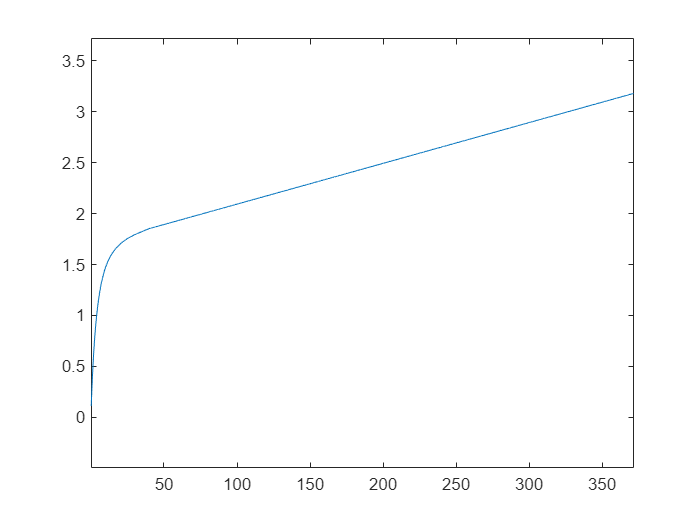

Time = 500;
Ts = 0.05;
no_samples = Time/Ts;
Time_vector = 0:Ts:Time-Ts;



% ================================================================= initial conditions
state_Variables = [M_PJJ; M_Con; T_m; m_dot_air; T_mlv; T_mv; M_lv; M_v; T_air; T_box; T_cargo];
init_conditions = [0.001; 2; 302; 1; 273; 273; 2; 0.0085; 273+10; 273+10; 273+10];



Input_OP_parameters = [U_fan_1, U_fan_2, Theta_1, Theta_2, omega, T_ambi];
Input_OP_values = [U_fan_1_op, U_fan_2_op, Theta_1_op, Theta_2_op, omega_op, T_ambi_OP];
f = subs(f, Input_OP_parameters, Input_OP_values);



% states(:,1) = init_conditions;
% 
% for i=2:no_samples
% f_current = subs(f,state_Variables,states(:,i-1));
% states(:,i) = states(:,i-1) + f_current*Ts;
% 
% end
states;
figure
plot(Time_vector,states(8,:)')

## Linearisation

Input_OP_parameters     = [U_fan_1,     U_fan_2,    Theta_1,    Theta_2,    omega,    T_ambi];
Input_OP_values         = [U_fan_1_op,  U_fan_2_op, Theta_1_op, Theta_2_op, omega_op, T_ambi_OP];
f_OP = subs(f, Input_OP_parameters, Input_OP_values)

$$f\_OP = \begin{array}{l} \left(\begin{array}{c} 6.7132e-05\,T_{m}-\sigma_{1}-0.4722\\ 6.7132e-05\,T_{m}-\sigma_{1}-0.0206\\ 17.1975-0.0568\,T_{m}\\ 0.0243-0.1000\,{\dot{m}}_{\mathrm{air}}\\ \frac{3.9397e-05\,\left(50\,T_{\mathrm{mv}}-50\,T_{\mathrm{mlv}}-0.9401\,M_{\mathrm{lv}}\,\left(3510\,T_{\mathrm{mlv}}-9.1886e+05\right)+\sigma_{4}\right)}{M_{\mathrm{lv}}}\\ -\frac{50\,T_{\mathrm{mlv}}-50\,T_{\mathrm{mv}}+\left(0.9401\,M_{\mathrm{lv}}-1\right)\,\left(1930\,T_{\mathrm{mv}}-5.1753e+05\right)+\sigma_{2}}{2.5383e+04\,M_{\mathrm{lv}}-27000}\\ 0.0117-\sigma_{3}\\ \sigma_{3}+\sigma_{1}-0.0057\\ 0.0227\,T_{\mathrm{box}}-0.0409\,T_{\mathrm{air}}+0.0182\,T_{\mathrm{cargo}}+0.9137\,{\dot{m}}_{\mathrm{air}}\,\left(\frac{9.9502e-04\,\left(\sigma_{4}+\sigma_{2}\right)}{{\dot{m}}_{\mathrm{air}}}+\frac{0.0195}{{\dot{m}}_{\mathrm{air}}}\right)+0.0178\\ 5.5928e-05\,T_{\mathrm{air}}-1.1186e-04\,T_{\mathrm{box}}+0.0164\\ 4.4743e-05\,T_{\mathrm{air}}-4.4743e-05\,T_{\mathrm{cargo}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=3.5000e-05\,{\left(\frac{4.5000e+05}{2.1303e+07\,M_{v}+7.3966e+03}\right)}^{0.8534}\\ \sigma_{2}=1005\,{\dot{m}}_{\mathrm{air}}\,\left(\frac{0.0195}{{\dot{m}}_{\mathrm{air}}}-T_{\mathrm{mv}}+268.9000\right)\\ \sigma_{3}=5.6385e-06\,M_{\mathrm{lv}}\,\left(3510\,T_{\mathrm{mlv}}-9.1886e+05\right)\\ \sigma_{4}=1005\,{\dot{m}}_{\mathrm{air}}\,\left(T_{\mathrm{mv}}-T_{\mathrm{mlv}}\right) \end{array}$$

solverVariables     = [M_PJJ;  M_Con; T_m;   m_dot_air;  T_mlv;   T_mv;  M_lv;  M_v;     T_air;    T_box;    T_cargo];
solverGuesses       = [1;      2;     302;   0.2;          273;     273;   2;   0.0085;  273+10;   273+10;   273+10];
eqpoint = vpasolve(f_OP == 0,solverVariables,solverGuesses)

eqpoint = struct with fields:
        M_PJJ: [0×1 sym]
        M_Con: [0×1 sym]
          T_m: [0×1 sym]
    m_dot_air: [0×1 sym]
        T_mlv: [0×1 sym]
         T_mv: [0×1 sym]
         M_lv: [0×1 sym]
          M_v: [0×1 sym]
        T_air: [0×1 sym]
        T_box: [0×1 sym]
      T_cargo: [0×1 sym]





%OP = struct2array(eqpoint);
%OP = OP(1,:)
% Operating_point_parameters= [M_lv,   M_v,    T_air,  T_box,  T_cargo,  T_m,   T_mv,   T_mlv,  m_dot_air ];
% Operating_point_values    = [OP(1),  OP(1),  OP(2),  OP(3),  OP(4),    OP(5), OP(6),  OP(7),  OP(8)     ];
Operating_point_parameters= [T_m,     m_dot_air,      T_mlv,     T_mv,       M_lv,     M_v,      T_air,      T_box,      T_cargo,      U_fan_1,    U_fan_2,    Theta_1,    Theta_2,    omega,    T_ambi];
Operating_point_values    = [T_m_OP,  m_dot_air_OP,   T_mlv_OP,  T_mv_OP,    M_lv_OP,  M_v_OP,   T_air_OP,   T_box_OP,   T_cargo_OP,   U_fan_1_op, U_fan_2_op, Theta_1_op, Theta_2_op, omega_op, T_ambi_OP];



## State space

% A matrix
% A_matrix = jacobian(f,[M_PJJ, M_Con, T_m, m_dot_air, T_mlv, T_mv, M_lv, M_v, T_air, T_box, T_cargo]);
A_matrix = jacobian(f_OP,[T_m, m_dot_air, T_mlv, T_mv, M_lv, M_v, T_air, T_box, T_cargo])




 A_matrix_lin = double(subs(A_matrix, Operating_point_parameters, Operating_point_values))

A_matrix_lin =     0.0001         0         0         0         0    0.0000         0         0         0
    0.0001         0         0         0         0    0.0000         0         0         0
   -0.0568         0         0         0         0         0         0         0         0
         0   -0.1000         0         0         0         0         0         0         0
         0         0   -0.9258    0.7958         0         0         0         0         0
         0         0    0.0035   -0.7773    0.0024         0         0         0         0
         0         0   -0.0099         0   -0.1409         0         0         0         0
         0         0    0.0099         0    0.1409   -0.0000         0         0         0
         0         0   -9.1372         0         0         0   -0.0409    0.0227    0.0182
         0         0         0         0         0         0    0.0001   -0.0001         0



% B matrix
B_matrix = jacobian(f,[U_fan_1, U_fan_2, Theta_1, Theta_2, omega ])

$$B\_matrix = \left(\begin{array}{ccccc} 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)$$


B_matrix_lin = subs(B_matrix, Operating_point_parameters, Operating_point_values);
B_matrix_lin = double(subs(B_matrix_lin, Input_OP_parameters, Input_OP_values ))

B_matrix_lin =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0




% Bd matrix
Bd_matrix = jacobian(f,[T_ambi]);
Bd_matrix_lin = subs(Bd_matrix, Operating_point_parameters, Operating_point_values);
Bd_matrix_lin = double(subs(Bd_matrix_lin, Input_OP_parameters, Input_OP_values))

Bd_matrix_lin =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


% C matrix

C = [0 0 0 0 0 0 0 0 1]; %last state is cargo temp

% state space system




G = ss(A_matrix_lin, [B_matrix_lin Bd_matrix_lin], C, 0);

Error using ss (line 355)
The "A" and "E" matrices must be square.


% Observability and controllability
eig(A_matrix_lin)


rank(obsv(A_matrix_lin, C))
rank(ctrb(A_matrix_lin, B_matrix_lin))


% Step response

t = 0:1:1000000;

u = [omega_op+0.3; Theta_1_op+0.2; Theta_2_op+0.2; U_fan_1_op+0.2; U_fan_2_op+0.2; T_ambi_OP+100].*ones(6,length(t));

u_control = u - [omega_op; Theta_1_op; Theta_2_op; U_fan_1_op; U_fan_2_op; T_ambi_OP].*ones(6,length(t));

u_control = [0.25; 0.25; 0.25; 0.25; 0.25; 0].*ones(6,length(t));

C_sigmaBot = [eye(9)];
[y,x] = lsim(A_matrix_lin,[B_matrix_lin Bd_matrix_lin],C_sigmaBot,0,u_control,t); %do the simulation
plot(t,y(:,6))
legend('Response')
